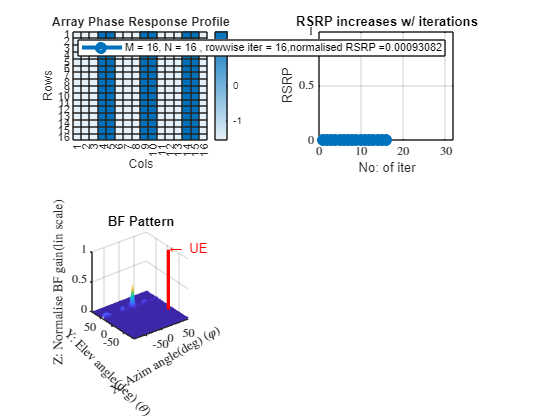

%% Implementation of Paper  - 
% Title: "RIS-Aided Wireless Communications: Prototyping, Adaptive Beamforming, and Indoor/Outdoor Field Trials"   
% Author : Xilong Pei

%% ASSUMPTIONS  : 
% 1) Phase shifts of the IRS can take binary values of either +pi/2 or -pi/2.

% 2) Only 1 Tx and 1 Rx antennas are there.

% 3) There is an AP, RIS and UE in the nearby vicinity. 

% 4) No direct path between AP and UE. 

% 5) RIS has 16x16 sub-atoms

% 6) We assume AP as the Tx and UE as the Rx(Downlink scenario)

% 7) Assume infinite coherence time.

%% AIM: 
% 1) Generate channels-  AP2RIS and RIS2UE

% 2) Calculate the optimum phase-shifts required for the RIS sub-atoms to
% get maximum SNR at the UE- using a fast-greedy algorithm. 

% 3) Calculate the Direction of Arrival (DoA) at the UE for this optimum PS
% Values


close all; clearvars; clc;
rng(2024);
global refl_elev; %#ok<GVMIS>
global refl_azim; %#ok<GVMIS>


% Number of sub-atoms(reflectors) in the horizontal and vertical dimensions(We assume a square RIS nH = nV)
nH = 16; 
nV = 16;
nrefl = nH*nV;

% Impinging Beam  direction(range: -pi/2 to pi/2) 
% (DEFINED BY THE RELATIVE LOCATION OF RIS AND AP)
impinging_azim = pi/4;
impinging_elev = pi/4;


% Beam Steering direction
% (DEFINED BY THE POSITION OF USER)
refl_azim = -0.83*pi/2;
refl_elev =  0.25*pi/2;


% Frequency of operation and Wavelength
fc = ((5.15 +5.875)/2)*1e9 ;
lambda = physconst('LightSpeed')/fc; 


% Defining h_AP2RIS (Channel b/w AP and RIS)
arv1 = exp(-1i*pi*(0:(nH-1))*sin(impinging_azim)*cos(impinging_elev)).'; % RIS Reflector Array Phase Response
arv2 = exp(-1i*pi*(0:(nH-1))*sin(impinging_elev)).';
arv  = kron(arv1,arv2);
h_AP2RIS  = arv *exp(1i*2*pi*rand);


% Defining h_RIS2UE (Channel b/w RIS and UE)
arv1 = exp(-1i*pi*(0:(nH-1))*sin(refl_azim)*cos(refl_elev)).';
arv2 = exp(-1i*pi*(0:(nH-1))*sin(refl_elev)).';
arv  = kron(arv1,arv2);
h_RIS2UE  = arv *exp(1i*2*pi*rand);


% Compute optimim Array response of RIS
Psi_optimum = -angle(h_AP2RIS.*h_RIS2UE);
Psi_suboptimum_1bit = (pi/2) *sign(Psi_optimum);


%% Greedy Algorithm Implementation
% apr = 1i*(2*round(rand(nrefl,1))-1); % Set initial values.
apr = 1i*ones(nrefl,1);
rsrp_max = abs(sum(h_AP2RIS .* apr .*h_RIS2UE))^2;
rsrp_logs =[]; % For plotting purpose we are keeping logs

% Row wise raster

for j = 1: nH 
    apr_new = update_apr(apr,j,'rowwise',nH,nV);
    rsrp_curr = abs(sum(h_AP2RIS .* apr_new .*h_RIS2UE))^2; % This value has to be maximised using Greedy Algorithm
    
    if(rsrp_curr > rsrp_max)
        apr = apr_new;
        rsrp_max = rsrp_curr;
    end
    rsrp_logs = [rsrp_logs;rsrp_max];
    plotapr(apr,nH,nV,'rowwise',j,rsrp_logs,h_AP2RIS); 
end

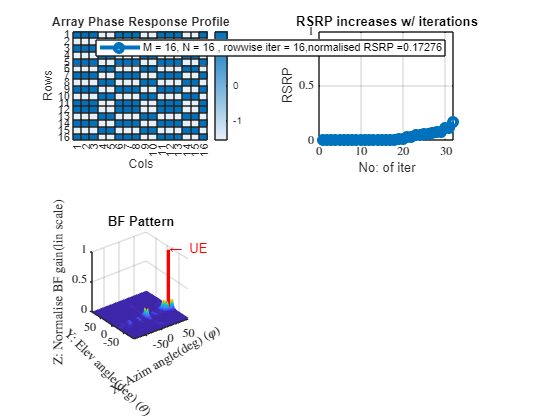


% Col wise raster

for j = 1: nV
    apr_new = update_apr(apr,j,'colwise',nH,nV);
    rsrp_curr = abs(sum(h_AP2RIS .* apr_new .*h_RIS2UE))^2; % This value has to be maximised using Greedy Algorithm
    
    if(rsrp_curr > rsrp_max)
        apr = apr_new;
        rsrp_max = rsrp_curr;
    end
    rsrp_logs = [rsrp_logs;rsrp_max];
    plotapr(apr,nH,nV,'rowwise',j,rsrp_logs,h_AP2RIS); 
end

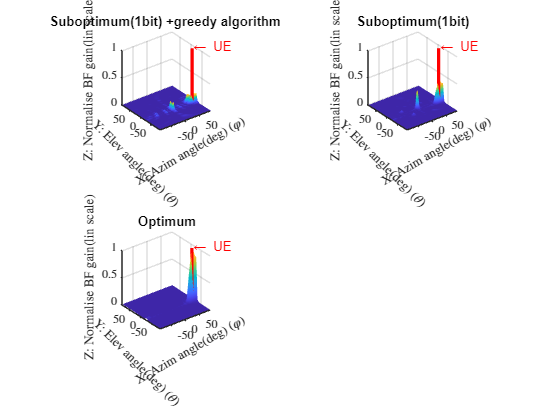


Psi_suboptimum_1bit_greedy = pi/2*(apr/1i);

figure;
% Compute the SNR at different azim, elev angles for suboptimal_psi value.
% Plot 1/3: Suboptimum(1bit) +greedy algorithm 
subplot(2,2,1);
BF = BF_pattern(nH,Psi_suboptimum_1bit_greedy,h_AP2RIS);
plot_BF_pattern(BF);
title("Suboptimum(1bit) +greedy algorithm ");

% Plot 2/3: Suboptimum(1bit) 
subplot(2,2,2);
BF = BF_pattern(nH,Psi_suboptimum_1bit,h_AP2RIS);
plot_BF_pattern(BF);
title("Suboptimum(1bit)");

% Plot 3/3: Optimum
subplot(2,2,3);
BF = BF_pattern(nH,Psi_optimum,h_AP2RIS);
plot_BF_pattern(BF);
title("Optimum");


%% -- END OF MAIN FUNCTION --


function [apr_new] = update_apr(apr,j,str,M,N)

    apr_new = reshape(apr,[M,N]);
    if(strcmp(str,'rowwise'))
        apr_new(:,j) = -apr_new(:,j);
    end

    if(strcmp(str,'colwise'))
        apr_new(j,:) = -apr_new(j,:);
    end
    apr_new = apr_new(:);

end

function plotapr(apr,nH,nV,rowcol,j,rsrp,h_AP2RIS)
    clf;
    cdata = (pi/2)*sign(imag(reshape(apr,[nH,nV])));
    subplot(2,2,1);
    heatmap(cdata,'XLabel','Cols','YLabel','Rows');title("Array Phase Response Profile");
    subplot(2,2,2); rsrp_norm = rsrp/((nH*nV)^2); plot(rsrp_norm,'-o','LineWidth',3); title("RSRP increases w/ iterations");xlim([0,nH+nV]); ylim([0,1]);
    str = strcat("M = " ,num2str(nH), ", N = ",num2str(nV)," , " ,rowcol," iter = " ,num2str(j),",normalised RSRP =",num2str(rsrp(end)/((nH*nV)^2)));
    xlabel("No: of iter");
    ylabel("RSRP");
    legend(str);grid on;hold on;
    subplot(2,2,3);
    BF = BF_pattern(nH,pi/2*(apr/1i),h_AP2RIS);
    plot_BF_pattern(BF); hold on;
    title("BF Pattern");
    pause(.1);
end

function BF = BF_pattern(nH,Psi,h_AP2RIS)

    global angleGrid; %#ok<GVMIS>
    global azimGrid; %#ok<GVMIS>
    global elevGrid; %#ok<GVMIS>
    gradations = 60;

    angleGrid= linspace(-pi/2,pi/2,gradations);
    [azimGrid,elevGrid] = meshgrid(angleGrid, angleGrid);
    BF = zeros(size(azimGrid));


    h_subopt = conj(h_AP2RIS).*exp(-1i*Psi);
    % R = h_subopt*h_subopt';


    for i = 1:length(angleGrid)
        for j = 1:length(angleGrid)

            arrayResponseVector1 = exp(-1i*pi*(0:(nH-1))*sin(azimGrid(i,j))*cos(elevGrid(i,j))).';
            arrayResponseVector2 = exp(-1i*pi*(0:(nH-1))*sin(elevGrid(i,j))).';
            arrayResponseVector = kron(arrayResponseVector1,arrayResponseVector2);
            % BF(i,j) = 1/real((arrayResponseVector'/R)*arrayResponseVector);
            BF(i,j) = abs(sum(arrayResponseVector.* h_subopt ));
        end
        % disp([num2str(i) ' out of ' num2str(length(angleGrid)) ]);
    end
    BF =BF./256;
    BF = BF.^2;
end

function plot_BF_pattern(BF)


    global azimGrid; %#ok<GVMIS>
    global elevGrid; %#ok<GVMIS>
    global refl_elev; %#ok<GVMIS>
    global refl_azim; %#ok<GVMIS>

    set(groot,'defaultAxesTickLabelInterpreter','latex');
    surf(azimGrid*180/pi, elevGrid*180/pi, BF,'FaceAlpha',1);
    shading interp;
    xlim([-90,90]);ylim([-90,90]);
    xlabel('X: Azim angle(deg) ($\varphi$)','Interpreter','latex','rotation', 30);
    ylabel('Y: Elev angle(deg) ($\theta$)','Interpreter','latex','rotation', -45);
    zlabel('Z: Normalise BF gain(lin scale)','Interpreter','latex');
    axis square
    hold on; plot3([-refl_azim*180/pi,-refl_azim*180/pi],[-refl_elev*180/pi,-refl_elev*180/pi],[0,1],'r','LineWidth',2.5);
    txt = '\leftarrow UE';
    text(-refl_azim*180/pi,-refl_elev*180/pi,1,txt,Color='r')
    hold off;

end